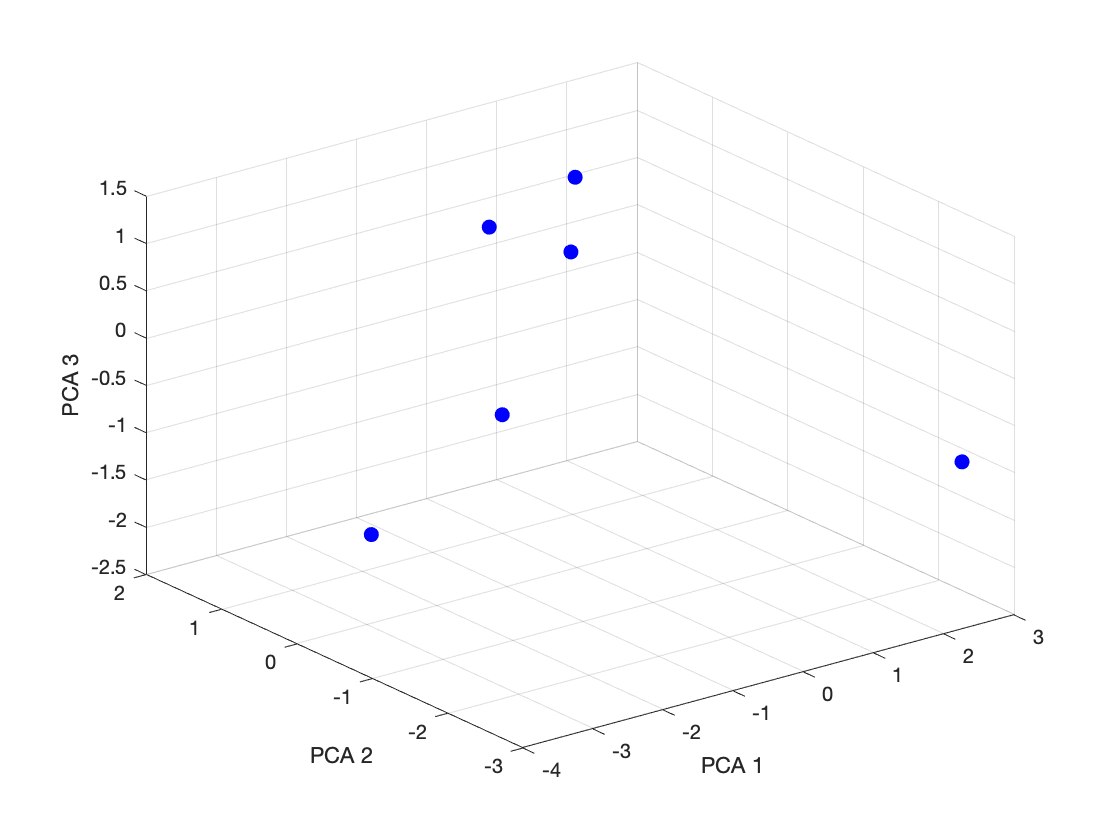

%read data
[M,col_id,row_id,titles] = readdata_p1();
[coeff,score,latent] = pca(M);
figure;
hold on; grid;
plot3(score(:,1),score(:,2),score(:,3),...
    '.','color','b','Markersize',20);
xlabel('PCA 1');
ylabel('PCA 2');
zlabel('PCA 3');
view(3);
saveas(gcf,'figures/pca.png');

% perform k-means clustering on the data points
k = 3;
[labels] = kmeans(M,k);
close all;
figure;
hold on; grid;
c = ['b';'r';'g'];
for i = 1 : k
    points = find(labels == i);
    fprintf('cluster %d:', i);
    disp(row_id(points));
    plot3(score(points,1),score(points,2),score(points,3),...
        '.','color',c(i),'Markersize',20);
end

cluster 1:

    25



cluster 2:

     1     2     4    16



cluster 3:

     8    29



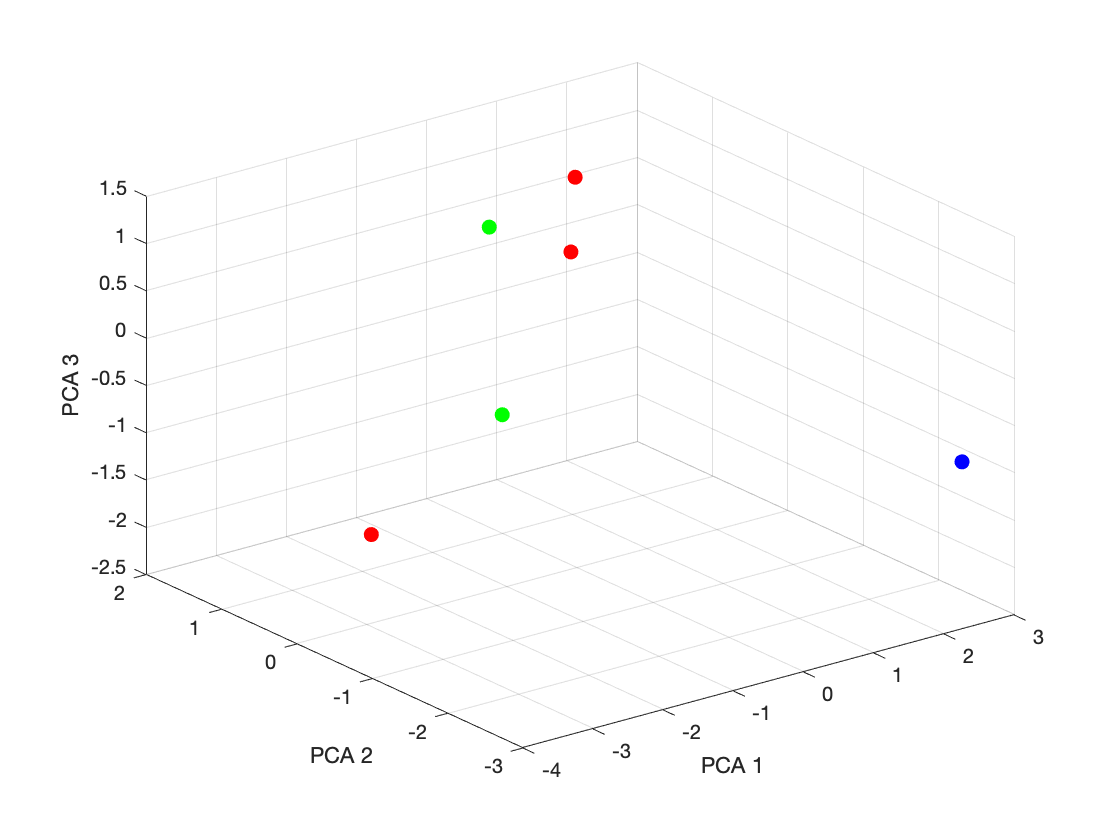

view(3);
xlabel('PCA 1');
ylabel('PCA 2');
zlabel('PCA 3');
saveas(gcf,'figures/kmeans-pca.png');

% set random initialization of W and H
[n,m] = size(M);
W = rand(n,k);
H = rand(k,m);

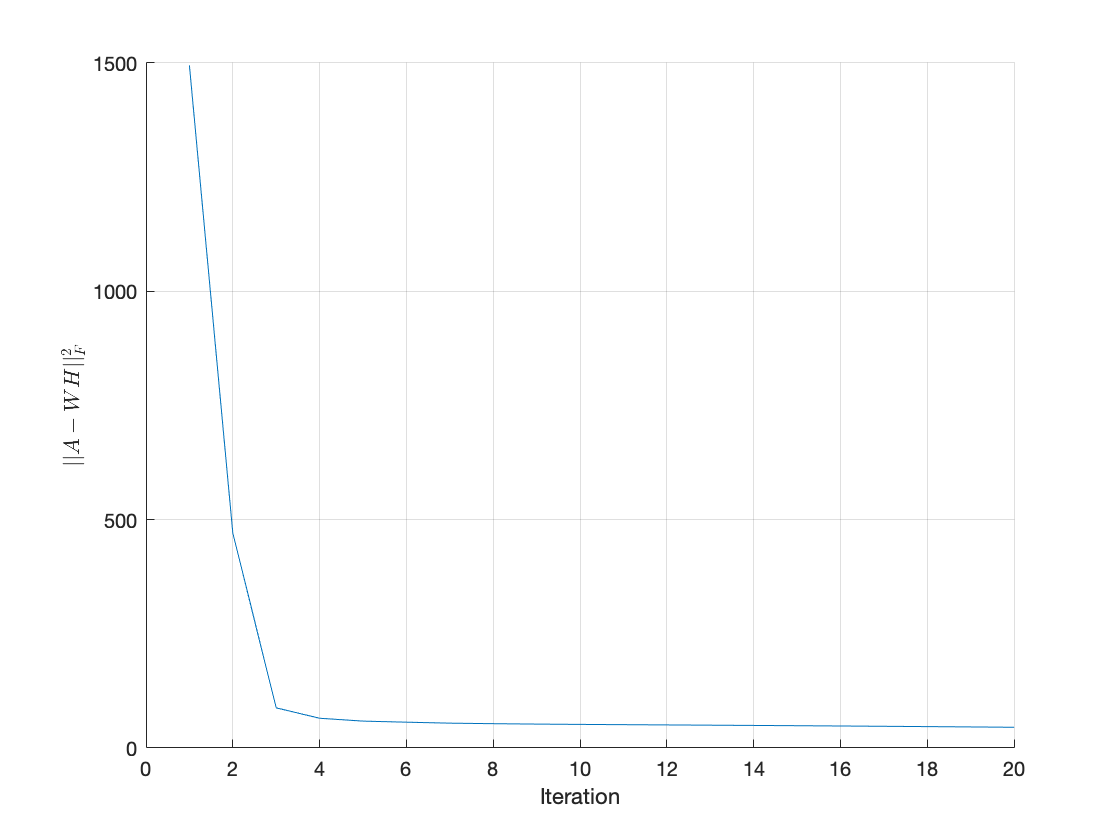

% projected gradient descent
maxiter = 20;
[fro_pgd, ~, ~] = PGD(M,k,maxiter,W,H);
close all;
figure;
hold on; grid;
plot(1:maxiter+1, fro_pgd);
xlim([0 maxiter]);
xlabel('Iteration');
ylabel('$||A-WH||_F^2$','interpreter','latex');
saveas(gcf,'figures/pgd.png');

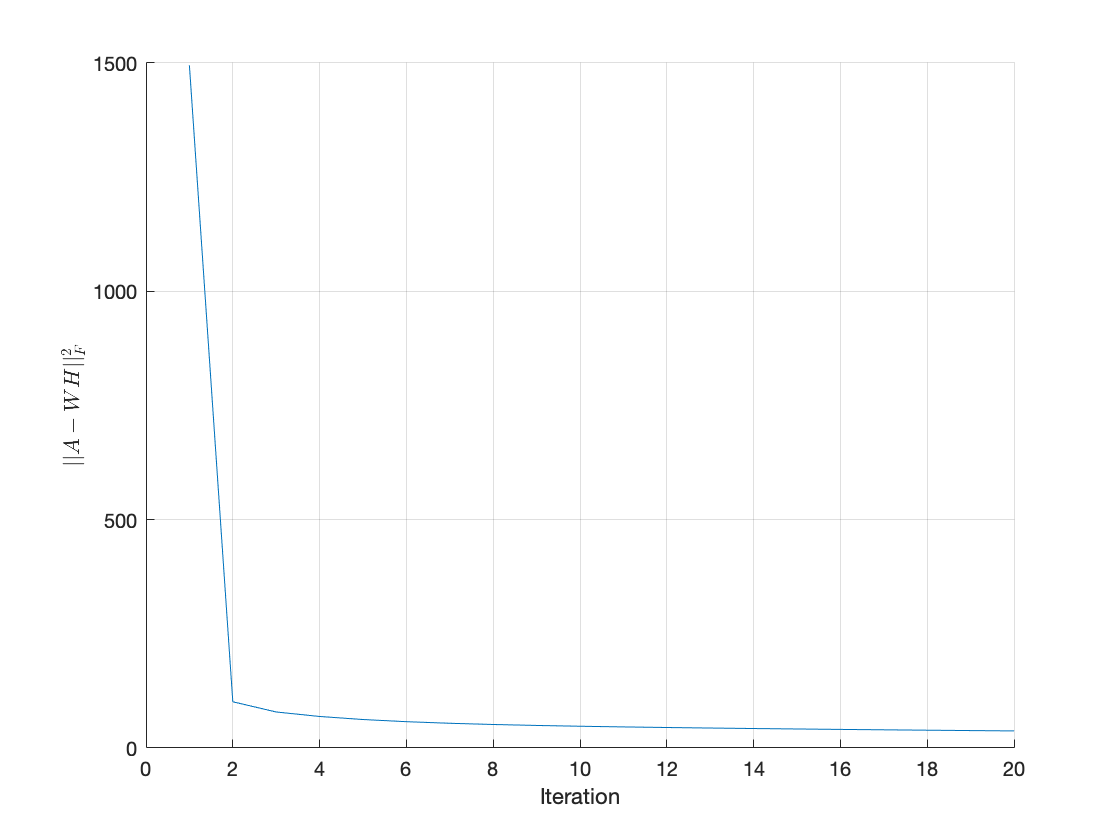

% the [Lee & Seung, 2001] multiplicative update scheme
[fro_mu, ~, ~] = MU(M,k,maxiter,W,H);
close all;
figure;
hold on; grid;
plot(1:maxiter+1, fro_mu);
xlim([0 maxiter]);
xlabel('Iteration');
ylabel('$||A-WH||_F^2$','interpreter','latex');
saveas(gcf,'figures/mu.png');

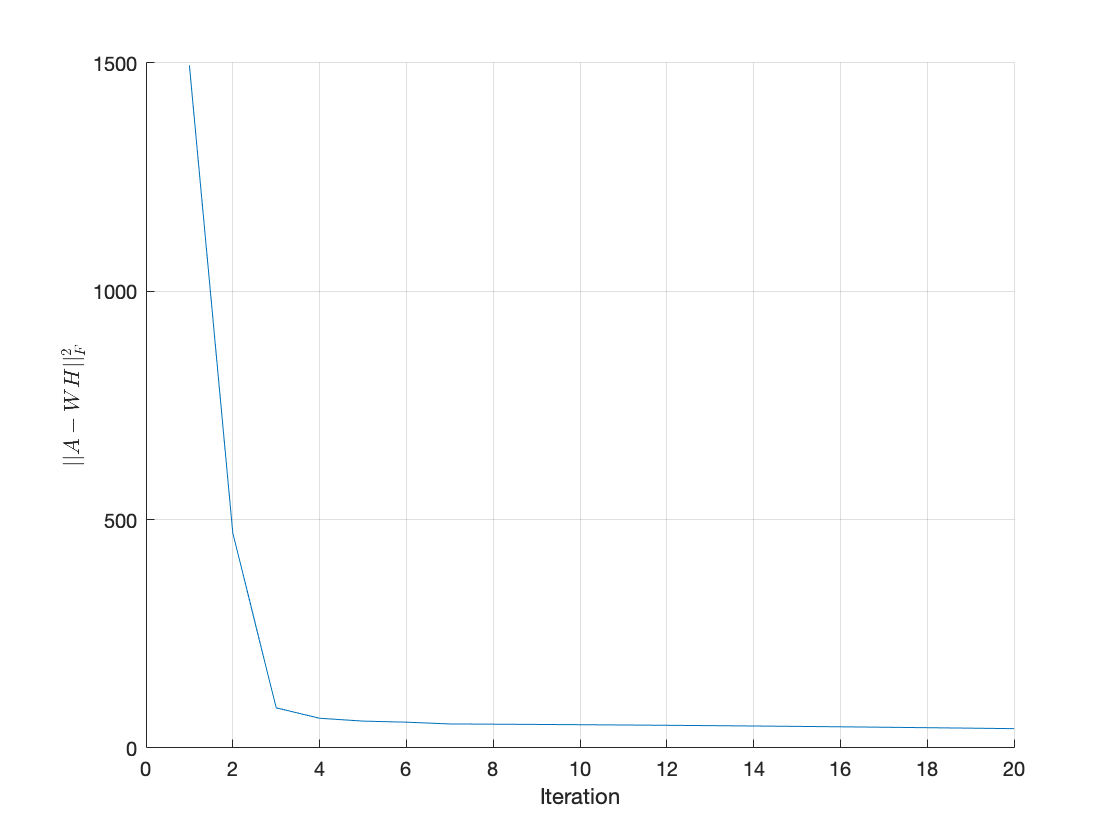

% begin with projected gradient descent
% then with multiplicative update
[fro1, W0, H0] = PGD(M,k,5,W,H);
[fro2, ~, ~] = MU(M,k,maxiter-5,W0,H0);
close all;
figure;
hold on; grid;
plot(1:maxiter+1, [fro1;fro2(2:end)]);
xlim([0 maxiter]);
xlabel('Iteration');
ylabel('$||A-WH||_F^2$','interpreter','latex');
saveas(gcf,'figures/pgd-mu.png');

fro_pgdmu = [fro1;fro2(2:end)];
fro_pgd(end)

ans = 44.6335

fro_mu(end)

ans = 36.6491

fro_pgdmu(end)

ans = 41.3099